# Derivative Rules for Transcendental Functions

For some common functions, applying the limit definition of the derivative requires more complicated limit proofs than those required for polynomials. This script presents the derivatives of sines, cosines, exponentials and natural logarithms through numerical approximation.

**Startup Instructions**

 This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor window.

 If you find the MATLAB coding in this script to be challenging, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## What is a Transcendental Function?

Have you encountered transcendental numbers like $e\approx 2.71828182459046$ or $\pi \approx 3.141592653589793$? They are called *transcendental* because they are not *algebraic,* that is they are not a root of any finite degree polynomial equation with integer coefficients. All rational numbers are algebraic, e.g., $r = \frac{p}{q}$ is a root of $y = qx-p$, but many irrational numbers are algebraic as well, e.g., $r=\sqrt{5}$ is a root of $y=x^2-5$. Notice that you can still approximate transcendental numbers by the sequence of decimal expansions. A *transcendental function* is a function that you can approximate by a sequence of polynomial functions, but that is not the solution to a polynomial equation itself. The most common transcendental functions are the exponential, logarithm, and trigonometric functions.

## Trigonometric Functions

Trigonometric functions are the family of functions that relate the ratios of sides to the angles in right triangles. 

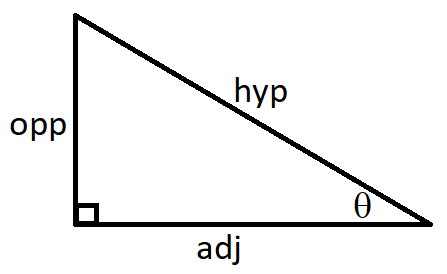

The abbreviations are

 opp = "length of the side opposite the angle $\theta$",                                  

adj = "length of the side between the right angle and the angle $\theta$", 

and 

hyp = "length of the hypotenuse".                                                      

### Sines & Cosines

The function $y = \sin(\theta)$ tracks the ratio $\frac{\text{opp}}{\text{hyp}}$. 

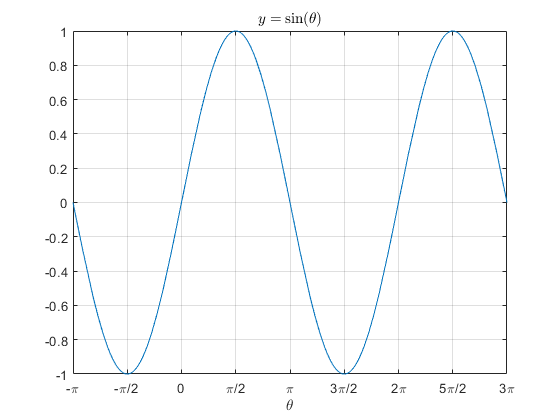

The function $y=\cos(\theta)$ tracks the ratio $\frac{\text{adj}}{\text{hyp}}$. 

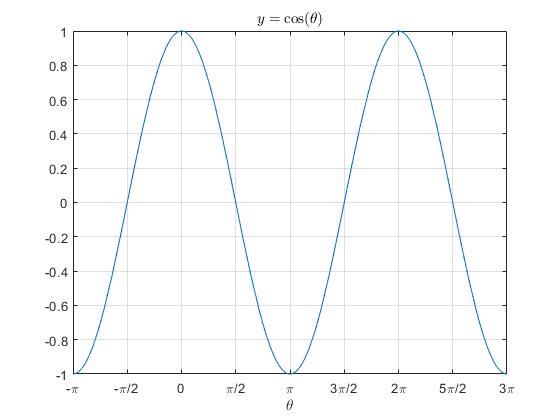

By placing a right triangle into a unit circle, the intimate relationship between sines and cosines becomes clear.

This is shown in [.mp4 animation](matlab:open('./unitCircleAnimation.mp4')) or by generating the animation below: 

 
unitCircleAnimation()

### Derivative of Sine

** Activity. **Let's try to determine the derivative $\frac{dy}{d\theta}$ of $y=\sin(\theta)$ by computing its numerical approximation. First, let's pick a step size $h$ to use in the difference quotient: 

$\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$,

and graph the result:

dt = 0.2;
 
graphApproxDer(@(t)sin(t),"sin",dt,[-pi 3*pi])

  **Try**. Make the value of the step size larger and smaller and observe the impact on the approximate derivative of $\sin(\theta)$that is shown in the graph above.

** Exercise 1**. Consider the approximate derivative $\frac{d}{d\theta}\left[\sin(\theta)\right]$ that is graphed above.

- Could the derivative be a polynomial function? Why or why not?

poly = "no";
if poly == "yes"
    disp("All polynomials p(t) diverge towards positive or negative infinity as p goes to infinity.")
    disp("That is not true of this derivative. It is not a polynomial.")
elseif poly == "no"
    disp("That is correct.")
    disp("This cannot be a polynomial because it does not have the correct limiting behavior.")
end

         2. Does the derivative have any asymptotes? Why or why not? If there are any asymptotes, what are they?

asymptotes = "idk";        
yasymp = 0.5;            
xasymp = 0.5;
if asymptotes == "yHoriz"
    disp("No, there is not a horizontal asymptote. Please try again.")
elseif asymptotes == "yVert"
    disp("No, there is not a vertical asymptote. Please try again.")
elseif asymptotes == "no"
    disp("Correct. The derivative does not have any asymptotes.")
end

         3. Is the derivative periodic? Why or why not? If it is periodic, what is the period and what is the peak amplitude?

periodic = -1;
if periodic == 1
    disp("Yes, this derivative is periodic. Please set the correct period and amplitude:") 
    period = 1;          amplitude = 2;
    if period == 2*pi
        disp("The period is correct.")
    elseif abs(period-2*pi)< .0033
        disp("Please use the exact value pi rather than the approximation 3.14.")
    elseif period == 1
        disp("The correct value of the period is not 1.")
        disp("Dashed blue lines show the proposed period.")
    else
        disp("The period is incorrect. Please try again.")
        disp("Dashed blue lines show the proposed period.")
    end
    if amplitude == 1
        disp("The amplitude is 1, that is correct.")
    elseif abs(amplitude-1)<.01
        disp("Please be more precise. The amplitude is an integer.")
    elseif amplitude == 2
        disp("The amplitude is not 2.")
        disp("Dotted red lines show the proposed amplitude.")
    else
        disp("The amplitude is incorrect. Please try again.")
        disp("Dotted red lines show the proposed amplitude.")        
    end
    graphApproxDer(@(t)sin(t),"sin",dt,[-pi 3*pi])
    if abs(amplitude)>1
        ylim([-1.1 1.1*abs(amplitude)]);
    end
    hold on
    xline(0,"b--")
    xline(period,"b--")
    yline(0,"r:")
    yline(amplitude,"r:")
    hold off
elseif periodic == 0
    disp("No, that is incorrect. Does this function ever repeat?")
end

** Exercise 2**. Taking into account the results of Exercise 1, the derivative $y'(\theta)$ should be a function that you recognize. Use the independent variable name `t for `$\theta$, what is the derivative of `sin(t) `with respect to `t`?

syms t
derGuess = @(t) t;
 
checkSinDer(derGuess)

### Derivative of Cosine

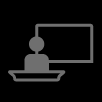** Activity**. Let's try to determine the derivative $\frac{dy}{d\theta}$ of $y=\cos(\theta)$ by computing its numerical approximation just as we did for $\sin(\theta)$ up above. First, let's pick a step size $h$ to use in the difference quotient, $\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$, and graph the result again.

dt = 0.2;
 
graphApproxDer(@(t)cos(t),"cos",dt,[-pi 3*pi])

Remember that the derivative of $y=\sin(\theta)$ was $y' = \sin\left(\theta+\frac{\pi}{2}\right)$. It appears that the derivative of $y=\cos(\theta)$ is also a sinusoidal function with the same amplitude. Use the slider to test values of the phase shift $\phi$ to determine the function $\frac{d}{d\theta}\left[\cos(\theta)\right] = \cos(\theta+\phi)$. You want the blue line to cover the black points.

mult = 0;
graphApproxDer(@(t)cos(t),"cos",dt,[-pi 3*pi])
hold on
graphDerGuess(@(t)cos(t),mult)
hold off

Once you have chosen the best possible function to fit the approximate derivative, you can check your result here using `t` as your independent variable. If you wish, you may also use `phi` for the value $\phi$ you set above or `pi` for the value $\pi$ :

phi = mult*pi;
syms(t)
cosDerGuess = @(t) t*phi*pi;
checkCosDer(cosDerGuess)

  **Try **

What happens if we look at the derivative of $y=\sin(c\theta)$ for some constant value $c$?

dt = 0.021;
c = 3;
 
graphApproxDer(@(t)sin(c*t),"sin",dt,[-pi 3*pi])
title("$y = \sin(c\theta)$ with $c =$"+c,"Interpreter","latex")
legend("$\sin(c\theta)$","Selected Points","Difference Quotient","AutoUpdate","off")
ylim = [-abs(1.1*c) abs(1.1*c)]

 **Reflect**

- What is the derivative $y'(\theta)$ for the function $y = \sin(7\theta)$?

- What do you think is the derivative $\frac{dy}{d\theta}$ for the function $y = \cos(c\theta)$ for some constant value $c$? Why?

- What do you think is the derivative $\frac{d}{d\theta}\left[\sin(\theta + \phi)\right]$ for some constant value $\phi$? Why?

## Second Derivatives

As discussed in [derivativeDefinition.mlx](matlab:open('./derivativeDefinition.mlx')), the derivative is a linear operator. In particular, since the derivative of a function is another function, it is possible to take several derivatives in sequence:

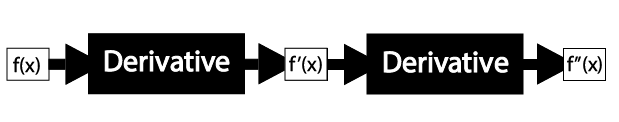

Let's assume the units of $f(x)$ are frogs and the units of $x$ are feet. Then 

$f(x)$ is the number of frogs                                                        

$f'(x)$ is the number of frogs per foot ($\frac{\text{frogs}}{\text{foot}}$)                               

$f^{\prime \prime}(x)$ is the number of frogs per square foot ($\frac{\text{frogs/foot}}{\text{foot}} = \frac{\text{frogs}}{\text{foot}^2}$)

 **Notation for Higher Order Derivatives**

Prime Notation

$f(x)$, $f'(x)$, $f''(x)$, $f'''(x)$, $f^{(iv)}(x)$, $f^{(v)}(x)$, $\ldots$, $f^{(n)}(x)$

Differential Notation

$f(x)$,     $\frac{df}{dx}$,     $\frac{d^2f}{dx^2}$,     $\frac{d^3f}{dx^3}$,     $\frac{d^4f}{dx^4}$,     $\frac{d^5f}{dx^5}$,     $\ldots$,     $\frac{d^nf}{dx^n}$

Operator Notation

$f(x)$, $\frac{d}{dx}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}[f]\right] = \frac{d^2}{dx^2}[f]$, $\frac{d}{dx}\left[\frac{d}{dx}\left[\frac{d}{dx}[f]\right]\right] = \frac{d^3}{dx^3}[f]$, $\ldots$, $\frac{d^n}{dx^n}[f]$

** Exercise 3**.

If the units of $g(y)$ are

gUnits = "";

and the units of $y$ are

yUnits = "";
 
if gUnits ~= "" && yUnits ~= ""
    opts = setOptions(gUnits,yUnits);
elseif gUnits ~= "" && yUnits == ""
    disp("You need to set values for the units of y to complete Exercise 3.")
elseif gUnits == "" && yUnits ~= ""
    disp("You need to set values for the units of g to complete Exercise 3.")
else
    disp("You need to set values for the units of g and the units of y to complete Exercise 3.")
end

Let

n = randi([2 5]);
disp("n =" + n)

If we calculate the `n`th derivative of $g$ with respect to $y$ the units will be which of the following?

dngdyn = 1;
try
checkGYUnits(dngdyn,n);
catch
    warning("You need to generate the problem in Exercise 3 before you can answer it.")
end

###  Application: Springs

Consider a simple mass-spring system with mass $m$ and stiffness coefficient $k>0$:

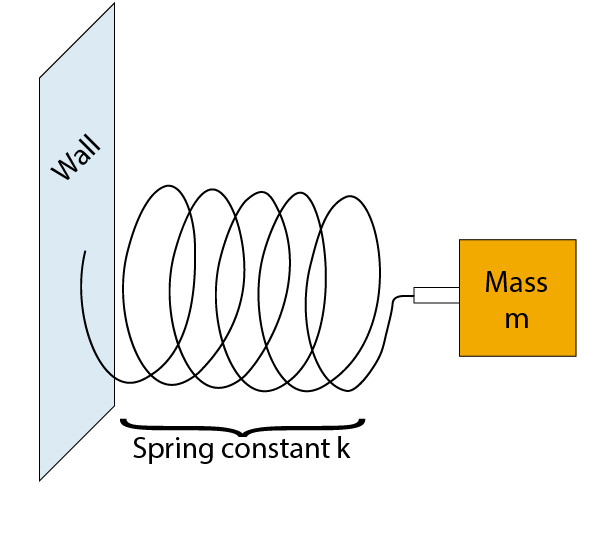

Then the motion of the mass as a function of the horizontal displacement $x = p(t)$ is given by a differential equation (that is an equation involving derivatives): 

                                         
$$\text{Force} = -k\cdot \left(\text{Displacement from Equilibrium}\right)$$



$$\text{Mass} \times \text{Acceleration} = -k\cdot p(t)$$
                            


$$m\cdot \frac{d}{dt}\left[\frac{d}{dt}\left[p(t)\right]\right] = -k\cdot p(t)$$
                      

$\frac{d^2p}{dt^2} = -\frac{k}{m}p(t)$,

where the force generated by the spring is acting in opposition to the displacement from equilibrium.  Thus, if $p(t)>0$, then the acceleration of the mass is in the negative direction towards zero and if $p(t)<0$, then the acceleration of the mass is in the positive direction towards zero. The equilibrium position, where the mass will stay at rest if it starts at rest is $p(t)=0$.

** Exercise 4**. Let's consider a case where $k=m=1$. Check whether any functions that you know satisfy this differential equation, that is if you calculated the second derivative $p''(t)$ that is the same function as $p(t)$ originally.

- $p(t) = x^n$ for any constant $n$

- 
$$p(t) = \sin(t)$$


- 
$$p(t) = \cos(t)$$


- 
$$p(t) = 3\sin(t)-7\cos(t)$$


Check the corresponding box if $p''(t) = p(t)$ and leave unchecked if $p''(t)\neq p(t)$.

one = false; two = false; three = false; four = false;
checkEqns(one,two,three,four);
 

 **Reflect**

- Why are there multiple different functions that all solve the same differential equation?

- Can you sketch a solution to a differential equation even if you don't know how to write the solution as a function? Why or why not?

- Can you find a solution to the differential equation when $k$ and $m$ are not both 1? For instance, what about $\frac{d^2p}{dt^2} = -4p$? 

## Exponential Functions

The full beauty of exponential functions only starts to come into focus when you consider them in the realm of calculus. 

  **Pro-tip**. In MATLAB, use the command exp(2*x) for $e^{2x}$.

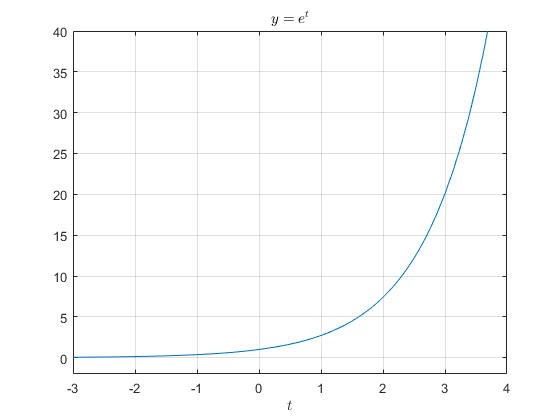

** Demonstration**. Let's take the same approach we did with $y=\cos(\theta)$ and compute and graph some values of the difference quotient 


$$\text{Difference Quotient} = \frac{e^{t+h}-e^{t}}{h} = e^t\left(\frac{e^h-1}{h}\right)$$


dt = 0.36;
 
syms t
graphApproxDer(@(t)exp(t),"exp",dt,[-3 4])

  **Try **Set some different values of $h$ using the slider. Then check your hypothesis. Remember to use `t` as the independent variable.

myGuess = @(t)exp(t);
 
checkExpDer(myGuess);

### ** Application: Population Growth**

Say we have a population of bunnies like these:

              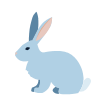    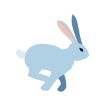      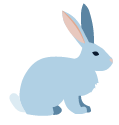        

If the number of bunnies at time $t$ in years is modelled by the function $B(t)$, and at time $0$ the bunny population is $100$, what is happening to the bunny population over time if $\frac{dB}{dt} = B(t)$?

 **Reflect**

- What type of function is its own derivative? How can you set the initial value to 100?

- What does this imply about the bunny population over the long term? 

- In what ways is this model realistic? In what ways is it unrealistic? 

** Activity**. The difference quotient approximation to the derivative can be used to approximate the solution to a differential equation with a known initial value. Say there are 100 bunnies to start, so $B(0)=100$. Each year, all the bunnies reproduce. Assuming that the bunny population is half male and half female and that the average litter size is $k$, that means that the number of new baby bunnies is given by $\frac{dB}{dt} = k\left(\frac{B(t)}{2}\right)$, so 

$\frac{B(t+h)-B(t)}{h} \approx k\left(\frac{B(t)}{2}\right)$. 

Thus, 

$B(t+h) = B(t) + hk\left(\frac{B(t)}{2}\right)$.

  **Try**. Run this code with different choices for `k` and the total number of years. How do your results change?

k = 5;
tend = 5;
 
tdata = 0:tend;             % Set up a time vector 
Bdata = size(tdata);        % Initialize a vector to use for the bunny population
Bdata(1) = 100;             % Set B(0)=100
for j = 1:length(tdata)-1
    Bdata(j+1) = Bdata(j) + k*(Bdata(j)/2);    % Update the population at each timestep 
end
plot(tdata,Bdata)           % Plot the calculated bunny population versus time
hold on
plot(tdata,100*exp(tdata))  % Add the plot of 100*e^t versus time
hold off
title("Modelling the Bunny Population")
xlabel("t (years)")
ylabel("# of Bunnies")
legend("Numerical Model with k = " + k, "y = 100e^t")

 **Reflect**.

- Why are the two functions different?

- Which function is growing faster? Why?

- Can you find a parameter `k` where the Numerical Model is growing slower than $100e^t$? Can you find a parameter `k` where the Numerical Model is growing faster than $100e^t$? 

#### Refining the Population Model

As you can see, the first Bunny Population Model is very coarse, resulting in piecewise defined graphs that do not look like smooth curves because we are only checking on the bunny population once each year. In fact, rabbits mature very quickly and can have several litters of babies each year, so let's allow a bit more flexibility with the time step:

if ~exist("k","var")            % Set up the default parameters 
    k = 5;                      % in case the previous section hasn't run
end
if ~exist("tend","var")         % Set up the default parameters
    tend = 5;                   % in case the previous section hasn't run
end
dt = 0.25;
 
tData = 0:dt:tend;              % Set up a time vector with step size dt
BData = size(tData);            % Initialize a vector for the bunny population
BData(1) = 100;                 % Set B(0)=100
for j = 1:length(tData)-1
    BData(j+1) = BData(j)+dt*(k/2)*BData(j);   % Update the population at each timestep
end
plot(tData,BData)               % Plot the calculated bunny population versus time
hold on
scatter(tdata,Bdata)            % Add a scatter plot of the bunny population with dt=1
fplot(100*exp(t),[0 tend])      % Add a plot of 100*e^t versus time
hold off
title("Modelling the Bunny Population")
xlabel("t (years)")
ylabel("# of Bunnies")
legend("Numerical Model with k = " + k + " and step size " + dt,"Numerical Model with k = " + k + " and step size 1", "y = 100e^t")

 **Reflect**

- What is the impact on the model as the step size between generations approaches 0? Is it realistic to allow the step size to approach 0 here? Why or why not?

- What type of function solves the differential equation $\frac{dy}{dx} = ky$ for $k$ a constant? Does it matter what $k$ is?

- What type of function solves the differential equation $\frac{dy}{dx} = kx$ for $k$ a constant? Does it matter what $k$ is?

- What is the derivative $\frac{d}{dt}\left[e^{at}\right]$ for constant $a$? 

## Logarithms

A logarithm is the inverse operation to exponentiation. As noted above, calculus identifies a special role for an exponent with base $e$, so there is a corresponding role for the natural logarithm $\ln(t) = \log_e(t)$. There is one additional complication with logarithms because the domain of a logarithm is $(0,\infty)$. 

** Activity**. Predict the type of function that will be the derivative of a natural logarithm and then run the code to generate a graph of the approximate derivative of $\ln(t)$.

dt = 0.1;
 
graphApproxDer(@(t)log(t),"ln",dt,[0 8])

  **Try **Set the step size to various values and predict the function that is the derivative of $\ln(t)$. 

** Exercise 5**. Consider the graph of the approximate value of the derivative $\frac{d}{dt}\left[\ln(t)\right]$.

- Could the derivative be a polynomial function? Why or why not?

poly = "idk";
if poly == "yes"
    disp("All polynomials p(t) diverge towards positive or negative infinity as p goes to infinity.")
    disp("That is not true of this derivative. It is not a polynomial.")
elseif poly == "no"
    disp("That is correct.")
    disp("This cannot be a polynomial because it does not have the correct limiting behavior.")
end

         2. Does the derivative have any asymptotes? Why or why not? If there are any asymptotes, what are they?

asymptotes = "idk";
if asymptotes == "yHoriz"
    disp("Yes, there is a horizontal asymptote.")
    disp("Adjust the horizontal asymptote to to correct:")
        yasymp = 3;            
        xasymp = 3;
    hold on
    plot([0 8],[yasymp yasymp],"b--")
    formatTitle = "Approximating the derivative of $y = \\%s(t)$ with step size $h=%.2f$";  
    str = compose(formatTitle,"ln",dt);
    title(str,"Asymptote $y=$" + asymp,"Interpreter","latex")
    hold off
elseif asymptotes == "yVert"
    disp("No, there is not a vertical asymptote. Please try again.")
elseif asymptotes == "no"
    disp("Yes, there is an asymptote. What type is it?")
end

         3. Is the derivative periodic? Why or why not? If it is periodic, what is the period and what is the amplitude?

periodic = 0;
period = "2*pi";          amplitude = "1";
if periodic == 1
    disp("No, this derivative is not periodic. Please try again.") 
elseif periodic == 0
    disp("That is correct. This derivative is not periodic.")
end


lnDerGuessType = "unknown";
checkLnDerGuessType(lnDerGuessType);

 **Reflect**

- Use numerical approximation or logarithm rules to determine the derivative $\frac{dy}{dx}$ of $y = \ln(cx)$ where $c$ is a constant. Does this match what you found for the other functions? Why or why not?

## Helper Functions

   If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor window.

function checkSinDer(fh)
% checkSinDer takes a function handle and checks whether it is equivalent
% to cos(t)
%
% fh is a function handle 
    syms t
    if cos(t) == fh(t)
        disp("Correct.")
    elseif cos(t) == simplify(fh(t))
        disp("Correct. It is more common to write cos(t), however.")
    else
        disp("Incorrect. What other sinusoidal functions do you know?")
    end
end

function graphApproxDer(fh,fs,dt,bds)
% graphApproxDer plots a function and calculates and plots its numerical
% derivative with step size dt
% 
% fh is a function handle to the function
% fs is the same function name as a string
% dt is the step size
% bds is a 1x2 vector [lower_bound upper_bound]
    syms t
    figure
    fplot(fh(t),bds);
    if bds(1) == -pi
        formatTitle = "Approximating the derivative of $y = \\%s(\\theta)$ with step size $h=$%.2f";
        xticks(-pi:pi/2:3*pi)
        xticklabels(["-\pi","-\pi/2","0","\pi/2","\pi","3\pi/2","2\pi","5\pi/2","3\pi"])
        formatLegend1 = "$\\%s(\\theta)$";
        formatLegend2 = "Difference Quotient: $\\left(\\theta, \\frac{\\%s(\\theta+h)-\\%s(\\theta)}{h}\\right)$";
        formatPts = "Selected Points: $\\left(\\theta, \\%s(\\theta)\\right)$";
    else
        formatTitle = "Approximating the derivative of $y = \\%s(t)$ with step size $h=$%.2f";     
        xticks(linspace(bds(1),bds(2),bds(2)-bds(1)+1));
        xticklabels(bds(1):bds(2));
        formatLegend1 = "$\\%s(t)$";
        formatLegend2 = "Difference Quotient: $\\left(t,\\frac{\\%s(t+h)-\\%s(t)}{h}\\right)$";
        formatPts = "Selected Points: $\\left(t,\\%s(t)\\right)$";
    end
    graphTitle = compose(formatTitle,fs,dt);
    line1 = compose(formatLegend1,fs);
    line2 = compose(formatLegend2,fs,fs);
    pts = compose(formatPts, fs);
    title(graphTitle,"Interpreter","latex")
    tVals = bds(1):dt:bds(2);
    yVals = fh(tVals);
    hold on
    scatter(tVals,yVals,100,"r.")
    hold off
% ax = gca;
% yLimVals = ax.YLim;
    derVals = (yVals(2:end)-yVals(1:end-1))/dt; % Numerical derivative
    mdPts = (tVals(2:end)+tVals(1:end-1))/2;    % Interval midpoints for graphing
    hold on
    plot(mdPts,derVals,"k.")
    legend(line1,pts,line2,...
    "Interpreter","latex","Location","southoutside","AutoUpdate","off")
    hold off
end

function graphDerGuess(fh,mult)
% graphDerGuess plots the function given by fh with a phase shift of mult*pi
%               and adds annotation noting that \phi = mult*pi on the plot
%               in the lower left hand quadrant of the plot
%
% fh is a function handle and mult is a number
    syms t
    fplot(fh(t+mult*pi),[-pi 3*pi],"b-","LineWidth",2)
    dim = [.22 .25 .2 .2];
    [num,den] = rat(abs(mult));
    if mult < 0
        num = -num;
    end
    if den ~= 1 && num ~= 1
        formatStr = "$\\phi = \\frac{%d\\pi}{%u}$";
        str = compose(formatStr, num, den);
    elseif den ~= 1 && num == 1
        formatStr = "$\\phi = \\frac{\\pi}{%u}$";
        str = compose(formatStr, den);    
    elseif num == 1 && den == 1
        str = "$\\phi = \\pi$";
    elseif num == -1 && den == 1
        str = "$\\phi = -\\pi$";
    else
        formatStr = "$\\phi = %d\\pi$";
        str = compose(formatStr,num);
    end
    annotation("textbox",dim,"String",str,"FitBoxToText","on",...
        "Interpreter","latex","EdgeColor",[1 1 1])
    legend(["$\cos(\theta)$" "Selected Points" "Approximate Derivative" "$\cos(\theta+\phi)$"],"Interpreter","latex")
end

function checkCosDer(fh)
% checkCosDer compares the function -sin(t) to fh(t) and prints a message
%             of success or failure using disp()
%
% fh is a function handle
    syms t
    if -sin(t) == fh(t)
        disp("Correct.")
    elseif -sin(t) == simplify(fh(t))
        disp("Correct. It is more common to write -sin(t), however.")
    else
        disp("Incorrect. Try to find a better fit.")
    end
end

function gyOpts = setOptions(gUnits,yUnits)
% gyOpts sets up the unit options
%
% gUnits are the units of the dependent variable
% yUnits are the units of the independent variable
    formatgy = "%s/%s";
    formatgy2 = "%s/%s^2";
    formatgy3 = "%s/%s^3";
    formatgy4 = "%s/%s^4";
    formatgy5 = "%s/%s^5";
    gyOpts = compose([formatgy,formatgy2,formatgy3,formatgy4,formatgy5],gUnits,yUnits);
    disp("Option 1: " + gyOpts(1))
    disp("Option 2: " + gyOpts(2))
    disp("Option 3: " + gyOpts(3))
    disp("Option 4: " + gyOpts(4)) 
    disp("Option 5: " + gyOpts(5)) 
end

function checkGYUnits(myAnswer,n)
% checkGYUnits checks myAnswer against the value n
%
% myAnswer is an integer in the range 1-5
% n is an integer in the range 2-5
    if myAnswer == n
        disp("Correct!")
    else
        disp("Remember that every derivative involves dividing by the units of the independent variable.")
        disp("Please try again.")
    end
end

function checkEqns(a,b,c,d)
% checkEqns checks the truth of a, b, c, and d and prints feedback
%
% a, b, c, and d are boolean values
    if ~a && b && c && d
        disp("Correct!")
        disp(" Any linear combination of sines and cosines will be a solution to this differential equation.")
    else
        disp("Please check your derivatives.")
        disp("One of these functions does not work and three of them do.")
        disp("Why?")
    end
end

function checkExpDer(myGuess)
% checkExpDer compares myGuess to exp(t)
%
% myGuess is a function handle
syms t
if myGuess == exp(t)
    disp("Correct!")
    disp("All functions of the form a^x for constant a and variable x have derivatives")
    disp("that are multiples of the original, but only for e^x is that multiple 1.")
else
    disp("Incorrect. What function does this look like?")
    disp("Remember that the MATLAB syntax for an exponential e^x is exp(x).")
    fplot(myGuess,[-3 4])
    hold on
    fplot(exp(t),[-3 4])
    hold off
    legend("My Guess","Derivative of $e^t$","Interpreter","latex","Location","northwest")
    ylim([-3 40])
end
end

function checkLnDerGuessType(myAnswer)
% checkLnDerGuessType plots a best-fit curve of form myAnswer and provides
%                     written feedback to the function type selected and
%                     information about the goodness of fit
%
% myAnswer is a string from the set 
%          ["unknown" "exponential" "polynomial" "rational"]
    tData = 0.01:.005:10;
    tData = tData';
    tMid = (tData(2:end)+tData(1:end-1))/2;
    DQCalc = (log(tData(2:end))-log(tData(1:end-1)))/.005;
    switch myAnswer
        case "unknown"
            disp("You can do better than that. The answer is a familiar type of function.")
            return
        case "exponential"
            disp("No, the derivative of a logarithm is not an exponential function.")
            [fnFit,fnGoF] = fit(tMid,DQCalc,"exp1");
        case "polynomial"
           disp("No, the derivative of a logarithm is not a polynomial.")
           [fnFit,fnGoF] = fit(tMid,DQCalc,"poly5");
        case "rational"
            disp("Yes, the derivative of a logarithm is a rational function.")
            [fnFit,fnGoF] = fit(tMid,DQCalc,"rat33","StartPoint",[0 1 0 0 0 0 0]);
    end
    plot(fnFit,tMid,DQCalc)
    ylim([-5 30]);
    disp(fnFit)
    disp("The best fit of this type has an SSE of " + fnGoF.sse + " and an r^2 of " + fnGoF.rsquare + ".")
    disp("Good fits have an SSE near 0 and an r^2 near 1. What do you think?")
    if myAnswer == "rational"
        disp("  ")
        disp("In fact, the derivative of ln(t) is 1/t.")
    end
end

function unitCircleAnimation()
% unitCircleAnimation creates a large plot of the unit circle with an
%        animated inscribed right triangle and two small plots tracking the
%        cosine and sine of the angle in the center of the circle. It loops
%        twice around the entire circle over the course of 2.5 seconds
syms t
    for t0 = linspace(-pi-6*pi/500,3*pi,502)
        subplot(2,3,[1 2 4 5])
        fplot(cos(t),sin(t),[-pi 3*pi])
        title(["$x^2+y^2=1$ and the right triangle" "$(0,0)$, $(x,0)$, $(x,y)$"],"Interpreter","latex")
        axis square
        xlabel("$x$","Interpreter","latex")
        ylabel("$y$","Interpreter","latex")
        hold on
            scatter(0,0,"ko","filled")
            plot([0 cos(t0)],[0 0],"b-","LineWidth",2)
            plot([0 cos(t0)],[0 sin(t0)],"b-","LineWidth",2)
            plot([cos(t0) cos(t0)],[0 sin(t0)],"b-","LineWidth",2)
            scatter(cos(t0),0,"yo","filled","MarkerEdgeColor","m")
            scatter(cos(t0),sin(t0),"ro","filled")
        hold off
        subplot(2,3,3)
        fplot(t,sin(t),[-pi 3*pi])
        title("$y=\sin(\theta)$","Interpreter","latex")
        xlabel("$\theta$","Interpreter","latex")
        ylabel("$y$","Interpreter","latex")
        axis square
        hold on
            scatter(t0,sin(t0),"ro","filled")
        hold off
        subplot(2,3,6)
        fplot(t,cos(t),[-pi 3*pi])
        title("$x=\cos(\theta)$","Interpreter","latex")
        xlabel("$\theta$","Interpreter","latex")
        ylabel("$x$","Interpreter","latex")
        axis square
        hold on
            scatter(t0,cos(t0),"yo","filled","MarkerEdgeColor","m")
        hold off
        pause(.05)
    end
end